clc
clear all
close all
rng(0)

% continuous-time system
A1 = [
        [0,1,0,0,0,0];
        [0,0,1,0,0,0];
        [0,0,0,1,0,0];
        [0,0,0,0,1,0];
        [0,0,0,0,0,1];
        [1,0,0,0,0,0];
    ]

A1 =      0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     1     0     0     0     0     0


G1 = digraph(A1)

G1 =   digraph with properties:

    Edges: [6×2 table]
    Nodes: [6×0 table]


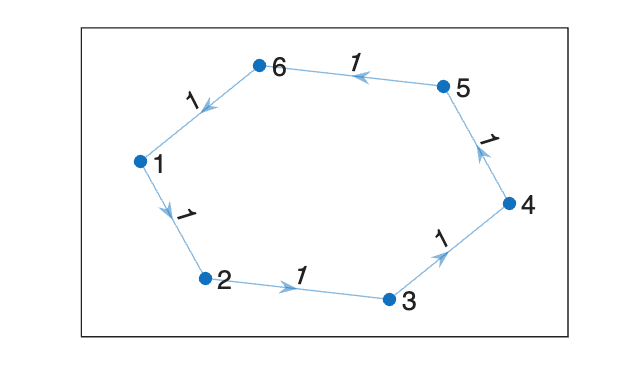

p = plot(G1, 'Layout', 'force');
p.EdgeLabel = G1.Edges.Weight;

dout1 = diag([1,1,1,1,1,1]);

L1 = dout1-A1

L1 =      1    -1     0     0     0     0
     0     1    -1     0     0     0
     0     0     1    -1     0     0
     0     0     0     1    -1     0
     0     0     0     0     1    -1
    -1     0     0     0     0     1



% defining ct-sys
N = size(L1, 1);
A = -L1;
B = zeros(N, 1); 
C = eye(N);     
D = zeros(N, 1); 
sys1 = ss(A, B, C, D);

pole(sys1)

ans =   -2.0000 + 0.0000i
  -1.5000 + 0.8660i
  -1.5000 - 0.8660i
  -0.5000 + 0.8660i
  -0.5000 - 0.8660i
  -0.0000 + 0.0000i



% corresponding discrete-time system
dout1_inv = dout1^-1;
A1_bar = dout1_inv*A1

A1_bar =      0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1
     1     0     0     0     0     0


G1_bar = digraph(A1_bar)

G1_bar =   digraph with properties:

    Edges: [6×2 table]
    Nodes: [6×0 table]


p = plot(G1_bar, 'Layout', 'force');
p.EdgeLabel = G1_bar.Edges.Weight;

% continuous-time system
A2 = [
        [0,1,0,0,0,1];
        [1,0,1,0,0,0];
        [0,1,0,1,0,0];
        [0,0,1,0,1,0];
        [0,0,0,1,0,1];
        [1,0,0,0,1,0];
    ]

A2 =      0     1     0     0     0     1
     1     0     1     0     0     0
     0     1     0     1     0     0
     0     0     1     0     1     0
     0     0     0     1     0     1
     1     0     0     0     1     0


G2 = digraph(A2)

G2 =   digraph with properties:

    Edges: [12×2 table]
    Nodes: [6×0 table]


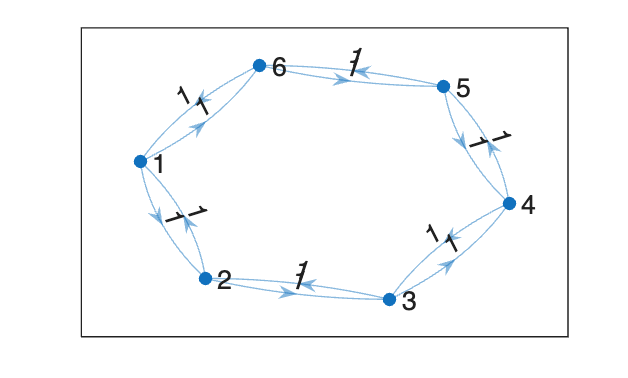

p = plot(G2, 'Layout', 'force');
p.EdgeLabel = G2.Edges.Weight;

dout2 = diag([2,2,2,2,2,2]);

L2 = dout2-A2

L2 =      2    -1     0     0     0    -1
    -1     2    -1     0     0     0
     0    -1     2    -1     0     0
     0     0    -1     2    -1     0
     0     0     0    -1     2    -1
    -1     0     0     0    -1     2



% defining ct-sys
N = size(L2, 1);
A = -L2;
B = zeros(N, 1); 
C = eye(N);     
D = zeros(N, 1); 
sys2 = ss(A, B, C, D);

pole(sys2)

ans =    -4.0000
   -3.0000
   -3.0000
   -1.0000
   -1.0000
    0.0000



% corresponding discrete-time system
dout2_inv = dout2^-1;
A2_bar = dout2_inv*A2

A2_bar =          0    0.5000         0         0         0    0.5000
    0.5000         0    0.5000         0         0         0
         0    0.5000         0    0.5000         0         0
         0         0    0.5000         0    0.5000         0
         0         0         0    0.5000         0    0.5000
    0.5000         0         0         0    0.5000         0


G2_bar = digraph(A2_bar)

G2_bar =   digraph with properties:

    Edges: [12×2 table]
    Nodes: [6×0 table]


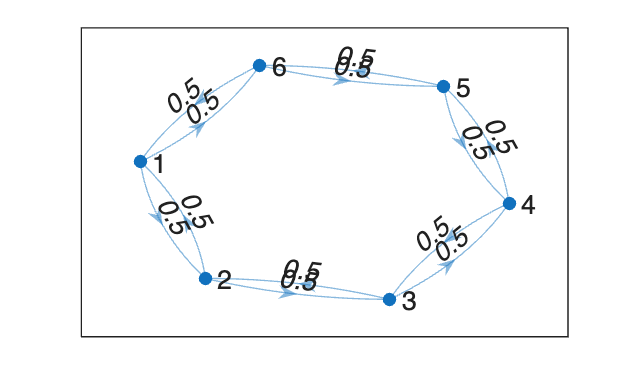

p = plot(G2_bar, 'Layout', 'force');
p.EdgeLabel = G2_bar.Edges.Weight;

% continuous-time system
A3 = [
        [0,1,1,1,1,1];
        [0,0,0,0,0,0];
        [0,0,0,0,0,0];
        [0,0,0,0,0,0];
        [0,0,0,0,0,0];
        [0,0,0,0,0,0];
    ]

A3 =      0     1     1     1     1     1
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


G3 = digraph(A3)

G3 =   digraph with properties:

    Edges: [5×2 table]
    Nodes: [6×0 table]


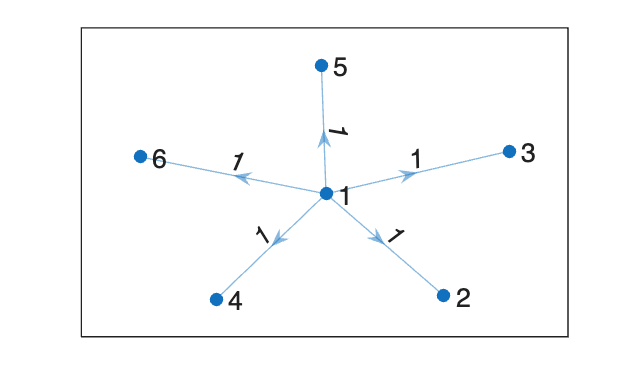

p = plot(G3, 'Layout', 'force');
p.EdgeLabel = G3.Edges.Weight;

dout3 = diag([5,0,0,0,0,0]);


L3 = dout3-A3

L3 =      5    -1    -1    -1    -1    -1
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0




% defining ct-sys
N = size(L3, 1);
A = -L3;
B = zeros(N, 1); 
C = eye(N);     
D = zeros(N, 1); 
sys3 = ss(A, B, C, D);


pole(sys3)

ans =     -5
     0
     0
     0
     0
     0




% corresponding discrete-time system
dout3_inv = dout3^-1;
A3_bar = dout3_inv*A3

A3_bar =          0    0.2000    0.2000    0.2000    0.2000    0.2000
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN
       NaN       NaN       NaN       NaN       NaN       NaN


G3_bar = digraph(A3_bar)

G3_bar =   digraph with properties:

    Edges: [35×2 table]
    Nodes: [6×0 table]


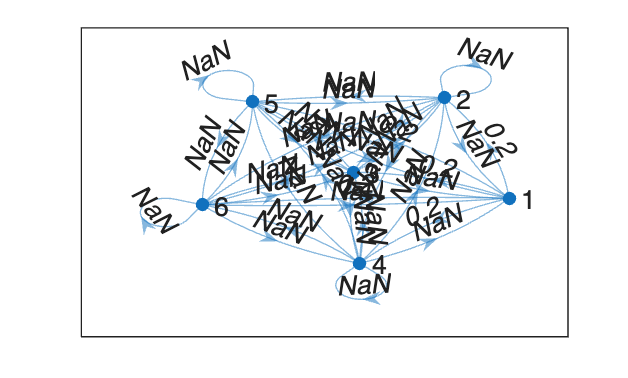

p = plot(G3_bar, 'Layout', 'force');
p.EdgeLabel = G3_bar.Edges.Weight;


% laplacian design to avoid numerical problems

epsilon = 1/5; %epsilon <= 1/max_dout 

% Matrice di aggiornamento discreta P = I - e*L
P3 = eye(N) - epsilon * L3

P3 =          0    0.2000    0.2000    0.2000    0.2000    0.2000
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000


G3_lap = digraph(P3)

G3_lap =   digraph with properties:

    Edges: [10×2 table]
    Nodes: [6×0 table]


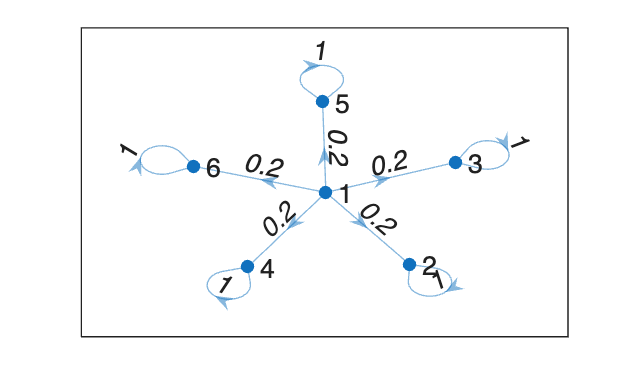

p = plot(G3_lap, 'Layout', 'force');
p.EdgeLabel = G3_lap.Edges.Weight;

% continuous-time system
A4 = [        
        [0,1,1,1,1,1];
        [1,0,0,0,0,0];
        [1,0,0,0,0,0];
        [1,0,0,0,0,0];
        [1,0,0,0,0,0];
        [1,0,0,0,0,0];
    ]

A4 =      0     1     1     1     1     1
     1     0     0     0     0     0
     1     0     0     0     0     0
     1     0     0     0     0     0
     1     0     0     0     0     0
     1     0     0     0     0     0


G4 = digraph(A4)

G4 =   digraph with properties:

    Edges: [10×2 table]
    Nodes: [6×0 table]


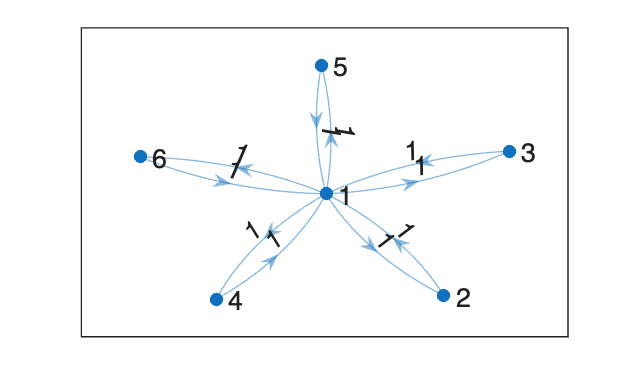

p = plot(G4, 'Layout', 'force');
p.EdgeLabel = G4.Edges.Weight;

dout4 = diag([5,1,1,1,1,1]);


L4 = dout4-A4

L4 =      5    -1    -1    -1    -1    -1
    -1     1     0     0     0     0
    -1     0     1     0     0     0
    -1     0     0     1     0     0
    -1     0     0     0     1     0
    -1     0     0     0     0     1




% defining ct-sys
N = size(L4, 1);
A = -L4;
B = zeros(N, 1); 
C = eye(N);     
D = zeros(N, 1); 
sys4 = ss(A, B, C, D);


pole(sys4)

ans =    -6.0000
   -1.0000
   -1.0000
   -1.0000
   -1.0000
    0.0000




% corresponding discrete-time system
dout4_inv = dout4^-1;
A4_bar = dout4_inv*A4

A4_bar =          0    0.2000    0.2000    0.2000    0.2000    0.2000
    1.0000         0         0         0         0         0
    1.0000         0         0         0         0         0
    1.0000         0         0         0         0         0
    1.0000         0         0         0         0         0
    1.0000         0         0         0         0         0


G4_bar = digraph(A4_bar)

G4_bar =   digraph with properties:

    Edges: [10×2 table]
    Nodes: [6×0 table]


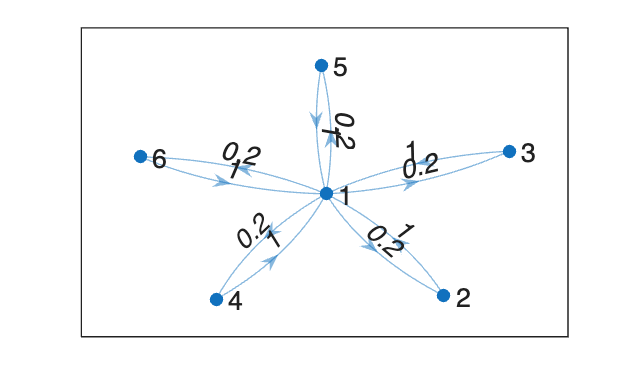

p = plot(G4_bar, 'Layout', 'force');
p.EdgeLabel = G4_bar.Edges.Weight;

% defining ct-sim environmnet
n = 6

n = 6

x0 =rand(n,1)

x0 =     0.8147
    0.9058
    0.1270
    0.9134
    0.6324
    0.0975


x0_mean = mean(x0)

x0_mean = 0.5818


t_final = 10

t_final = 10


tspan = [0 t_final];
K = 10

K = 10


dyn1 = @(t, x) -L1 * x;
dyn2 = @(t, x) -L2 * x;
dyn3 = @(t, x) -L3 * x;
dyn4 = @(t, x) -L4 * x;

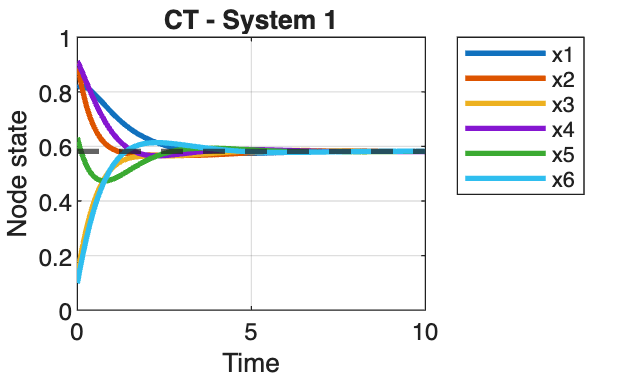

% sim 1
[t, x_out] = ode45(dyn1, tspan, x0);
figure;
plot(t, x_out, 'LineWidth', 2);
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata

title('CT - System 1');
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6','Location', 'northeastoutside');
grid on;


x1_inf = Simulate_Consensus(A1_bar,A1_bar,x0, K, 'sync')

x1_inf =     0.6324
    0.0975
    0.8147
    0.9058
    0.1270
    0.9134


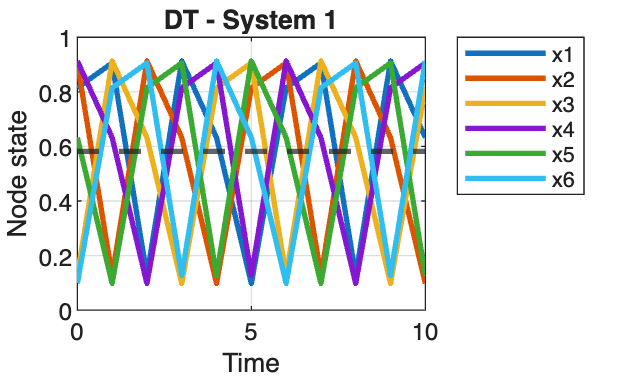

X1 = Simulate_Trajectory(A1_bar, A1_bar, x0, K, 'sync');

figure;
plot(0:K, X1', 'LineWidth', 2);  % linee più spesse
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata
grid on;
title('DT - System 1')
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6','Location', 'northeastoutside');

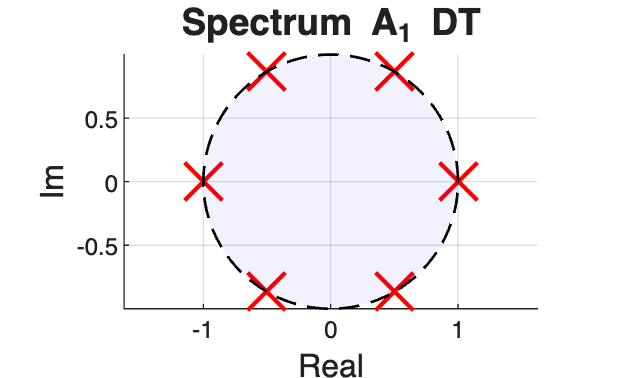


A = A1_bar;

figure;
autovalori = eig(A);
real_part = real(eig(A));
imag_part = imag(eig(A));
hold on;
plot(real_part, imag_part, 'rx', 'MarkerSize', 20, 'LineWidth', 1.5);
title('Spectrum A_1 DT', 'FontSize', 14);
xlabel('Real', 'FontSize', 12);
ylabel('Im', 'FontSize', 12);

theta = linspace(0, 2*pi, 200);
x_circle = cos(theta);
y_circle = sin(theta);
fill(x_circle, y_circle, 'b', 'FaceAlpha', 0.05, ...
     'EdgeColor', 'k', 'LineStyle', '--', 'LineWidth', 1);
axis equal;

grid on;
hold off;


fprintf('\n--- Lista degli Autovalori ---\n');


--- Lista degli Autovalori ---


for i = 1:length(autovalori)
    if imag(autovalori(i)) >= 0
        fprintf('λ_%d = %8.4f + %8.4fi\n', i, real(autovalori(i)), imag(autovalori(i)));
    else
        fprintf('λ_%d = %8.4f - %8.4fi\n', i, real(autovalori(i)), abs(imag(autovalori(i))));
    end
end

λ_1 =  -1.0000 +   0.0000i
λ_2 =  -0.5000 +   0.8660i


λ_3 =  -0.5000 -   0.8660i


λ_4 =   0.5000 +   0.8660i


λ_5 =   0.5000 -   0.8660i


λ_6 =   1.0000 +   0.0000i


fprintf('------------------------------\n');

------------------------------


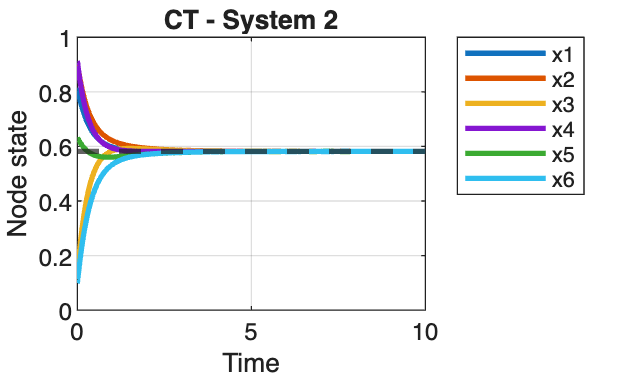

% sim 2
[t, x_out] = ode45(dyn2, tspan, x0);
figure;
plot(t, x_out, 'LineWidth', 2);
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata

title('CT - System 2');
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6','Location', 'northeastoutside');
grid on;



x2_inf = Simulate_Consensus(A2_bar, A2_bar, x0, K, 'sync')

x2_inf =     0.5250
    0.6392
    0.5243
    0.6392
    0.5248
    0.6384


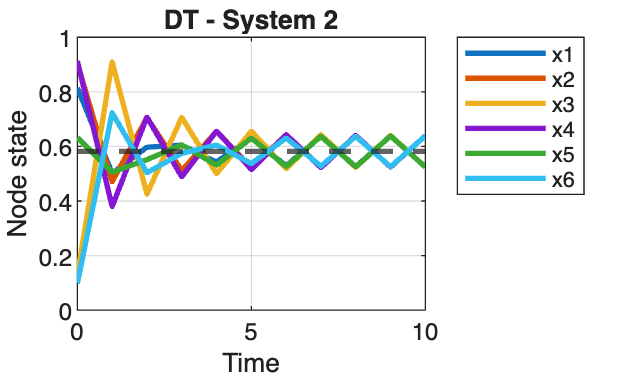

X2 = Simulate_Trajectory(A2_bar, A2_bar, x0, K, 'sync');

figure;
plot(0:K, X2', 'LineWidth', 2);  % linee più spesse
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata
grid on;
title('DT - System 2')
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6', 'Location', 'northeastoutside');

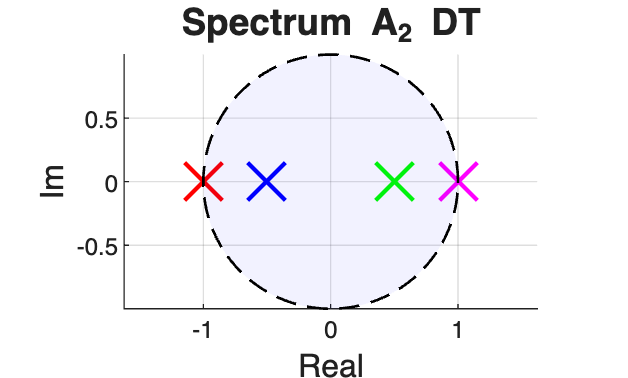


A = A2_bar;

figure;
autovalori = eig(A);
real_part = real(eig(A));
imag_part = imag(eig(A));
hold on;
plot(real_part(1), imag_part(1), 'rx', 'MarkerSize', 20, 'LineWidth', 1.5);
plot(real_part(2:3), imag_part(2:3), 'bx', 'MarkerSize', 20, 'LineWidth', 1.5);
plot(real_part(4:5), imag_part(4:5), 'gx', 'MarkerSize', 20, 'LineWidth', 1.5);
plot(real_part(6), imag_part(6), 'mx', 'MarkerSize', 20, 'LineWidth', 1.5);

title('Spectrum A_2 DT', 'FontSize', 14);
xlabel('Real', 'FontSize', 12);
ylabel('Im', 'FontSize', 12);

theta = linspace(0, 2*pi, 200);
x_circle = cos(theta);
y_circle = sin(theta);
fill(x_circle, y_circle, 'b', 'FaceAlpha', 0.05, ...
     'EdgeColor', 'k', 'LineStyle', '--', 'LineWidth', 1);
axis equal;

grid on;
hold off;


fprintf('\n--- Lista degli Autovalori ---\n');


--- Lista degli Autovalori ---


for i = 1:length(autovalori)
    if imag(autovalori(i)) >= 0
        fprintf('λ_%d = %8.4f + %8.4fi\n', i, real(autovalori(i)), imag(autovalori(i)));
    else
        fprintf('λ_%d = %8.4f - %8.4fi\n', i, real(autovalori(i)), abs(imag(autovalori(i))));
    end
end

λ_1 =  -1.0000 +   0.0000i
λ_2 =  -0.5000 +   0.0000i
λ_3 =  -0.5000 +   0.0000i
λ_4 =   0.5000 +   0.0000i
λ_5 =   0.5000 +   0.0000i
λ_6 =   1.0000 +   0.0000i


fprintf('------------------------------\n');

------------------------------


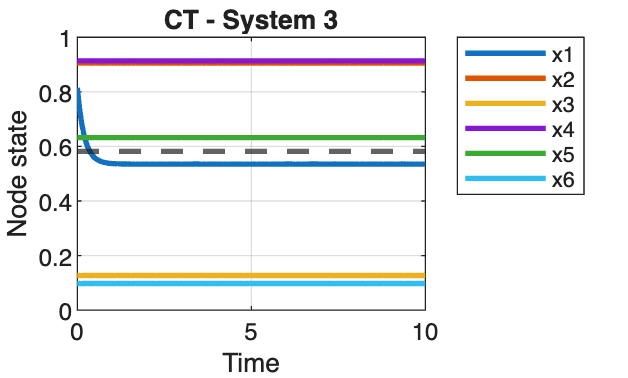

% sim 3
[t, x_out] = ode45(dyn3, tspan, x0);
figure;
plot(t, x_out, 'LineWidth', 2);
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata

title('CT - System 3');
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6','Location', 'northeastoutside');
grid on;


% Simulazione
x3_inf = Simulate_Consensus(A3_bar, A3_bar, x0, K, 'sync')

x3_inf =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN


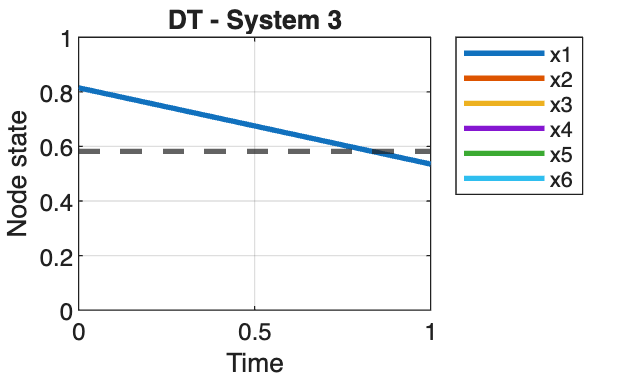

X3 = Simulate_Trajectory(A3_bar, A3_bar, x0, K, 'sync');

% Grafico
figure;
plot(0:K, X3', 'LineWidth', 2);  % linee più spesse
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata
grid on;
title('DT - System 3')
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6', 'Location', 'northeastoutside');

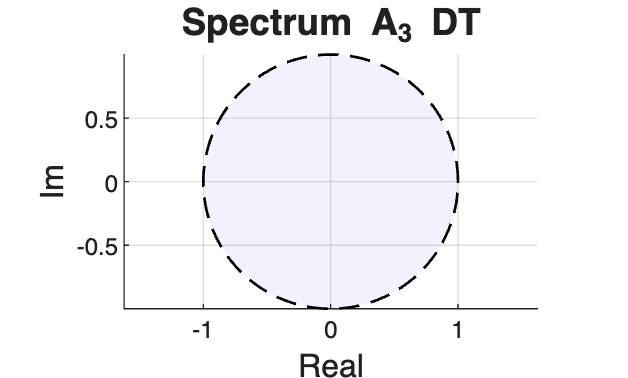


A = A3_bar;

figure;
autovalori = eig(A);
real_part = real(eig(A));
imag_part = imag(eig(A));
hold on;
plot(real_part, imag_part, 'rx', 'MarkerSize', 20, 'LineWidth', 1.5);
title('Spectrum A_3 DT', 'FontSize', 14);
xlabel('Real', 'FontSize', 12);
ylabel('Im', 'FontSize', 12);

theta = linspace(0, 2*pi, 200);
x_circle = cos(theta);
y_circle = sin(theta);
fill(x_circle, y_circle, 'b', 'FaceAlpha', 0.05, ...
     'EdgeColor', 'k', 'LineStyle', '--', 'LineWidth', 1);
axis equal;

grid on;
hold off;


fprintf('\n--- Lista degli Autovalori ---\n');


--- Lista degli Autovalori ---


for i = 1:length(autovalori)
    if imag(autovalori(i)) >= 0
        fprintf('λ_%d = %8.4f + %8.4fi\n', i, real(autovalori(i)), imag(autovalori(i)));
    else
        fprintf('λ_%d = %8.4f - %8.4fi\n', i, real(autovalori(i)), abs(imag(autovalori(i))));
    end
end

λ_1 =      NaN +   0.0000i
λ_2 =      NaN +   0.0000i
λ_3 =      NaN +   0.0000i
λ_4 =      NaN +   0.0000i
λ_5 =      NaN +   0.0000i
λ_6 =      NaN +   0.0000i


fprintf('------------------------------\n');

------------------------------


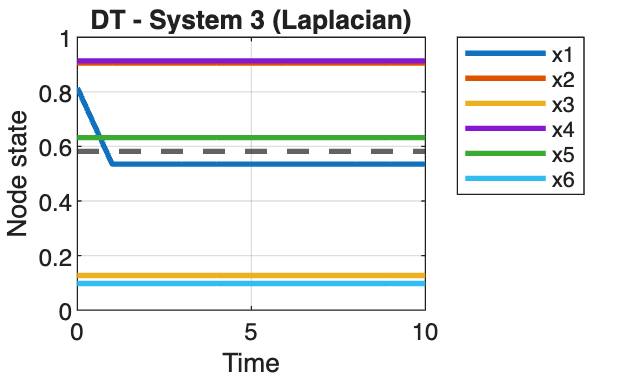




% con grafo fixato
x3_inf = Simulate_Consensus(P3, P3, x0, K, 'sync');
X3 = Simulate_Trajectory(P3, P3, x0, K, 'sync');

% Grafico
figure;
plot(0:K, X3', 'LineWidth', 2);  % linee più spesse
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata
grid on;
title('DT - System 3 (Laplacian)');
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6', 'Location', 'northeastoutside');

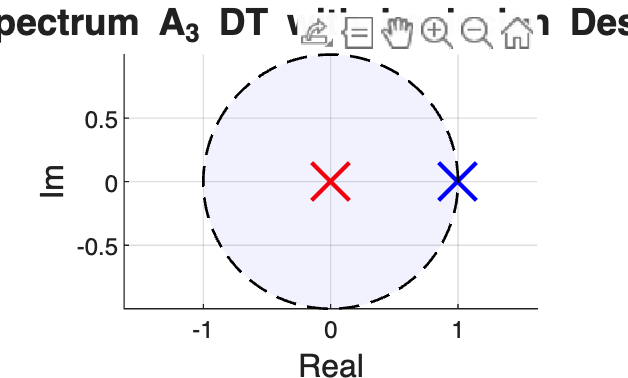


A = P3;

figure;
autovalori = eig(A);
real_part = real(eig(A));
imag_part = imag(eig(A));
hold on;
plot(real_part(1), imag_part(1), 'rx', 'MarkerSize', 20, 'LineWidth', 1.5);
plot(real_part(2:6), imag_part(2:6), 'bx', 'MarkerSize', 20, 'LineWidth', 1.5);

title('Spectrum A_3 DT with Laplacian Design', 'FontSize', 14);
xlabel('Real', 'FontSize', 12);
ylabel('Im', 'FontSize', 12);

theta = linspace(0, 2*pi, 200);
x_circle = cos(theta);
y_circle = sin(theta);
fill(x_circle, y_circle, 'b', 'FaceAlpha', 0.05, ...
     'EdgeColor', 'k', 'LineStyle', '--', 'LineWidth', 1);
axis equal;

grid on;
hold off;


fprintf('\n--- Lista degli Autovalori ---\n');


--- Lista degli Autovalori ---


for i = 1:length(autovalori)
    if imag(autovalori(i)) >= 0
        fprintf('λ_%d = %8.4f + %8.4fi\n', i, real(autovalori(i)), imag(autovalori(i)));
    else
        fprintf('λ_%d = %8.4f - %8.4fi\n', i, real(autovalori(i)), abs(imag(autovalori(i))));
    end
end

λ_1 =   0.0000 +   0.0000i
λ_2 =   1.0000 +   0.0000i
λ_3 =   1.0000 +   0.0000i
λ_4 =   1.0000 +   0.0000i
λ_5 =   1.0000 +   0.0000i
λ_6 =   1.0000 +   0.0000i


fprintf('------------------------------\n');

------------------------------


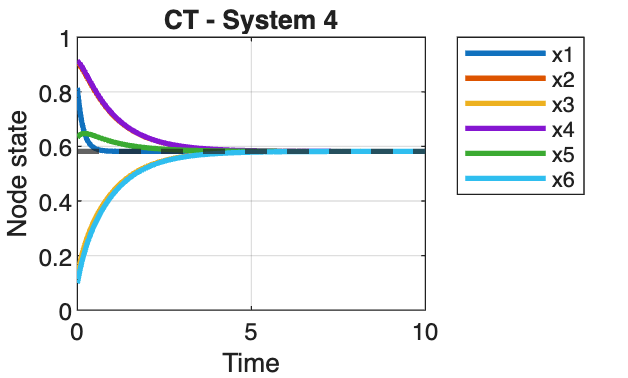

% sim 4
[t, x_out] = ode45(dyn4, tspan, x0);
figure;
plot(t, x_out, 'LineWidth', 2);
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata

title('CT - System 4');
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6','Location', 'northeastoutside');
grid on;


% Simulazione
x4_inf = Simulate_Consensus(A4_bar, A4_bar, x0, K, 'sync')

x4_inf =     0.8147
    0.5352
    0.5352
    0.5352
    0.5352
    0.5352


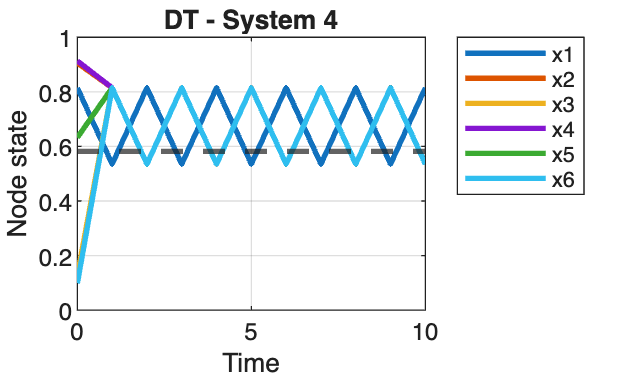

X4 = Simulate_Trajectory(A4_bar, A4_bar, x0, K, 'sync');

% Grafico
figure;
plot(0:K, X4', 'LineWidth', 2);  % linee più spesse
yline(x0_mean, '--', 'LineWidth', 2);  % linea tratteggiata
grid on;
title('DT - System 4')
xlabel('Time');
ylabel('Node state');
legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6', 'Location', 'northeastoutside');

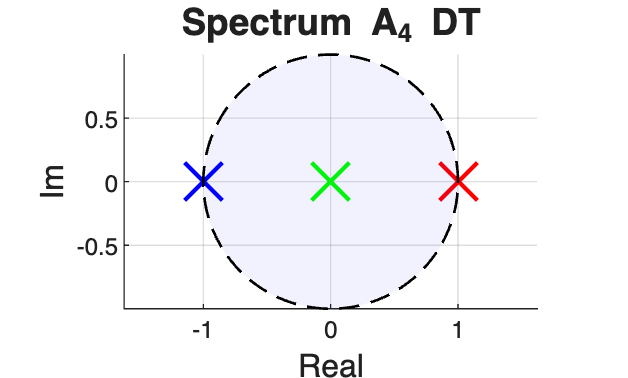


A = A4_bar;

figure;
autovalori = eig(A);
real_part = real(eig(A));
imag_part = imag(eig(A));
hold on;
plot(real_part(1), imag_part(1), 'rx', 'MarkerSize', 20, 'LineWidth', 1.5);
plot(real_part(2), imag_part(2), 'bx', 'MarkerSize', 20, 'LineWidth', 1.5);
plot(real_part(3:6), imag_part(3:6), 'gx', 'MarkerSize', 20, 'LineWidth', 1.5);

title('Spectrum A_4 DT', 'FontSize', 14);
xlabel('Real', 'FontSize', 12);
ylabel('Im', 'FontSize', 12);

theta = linspace(0, 2*pi, 200);
x_circle = cos(theta);
y_circle = sin(theta);
fill(x_circle, y_circle, 'b', 'FaceAlpha', 0.05, ...
     'EdgeColor', 'k', 'LineStyle', '--', 'LineWidth', 1);
axis equal;

grid on;
hold off;


fprintf('\n--- Lista degli Autovalori ---\n');


--- Lista degli Autovalori ---


for i = 1:length(autovalori)
    if imag(autovalori(i)) >= 0
        fprintf('λ_%d = %8.4f + %8.4fi\n', i, real(autovalori(i)), imag(autovalori(i)));
    else
        fprintf('λ_%d = %8.4f - %8.4fi\n', i, real(autovalori(i)), abs(imag(autovalori(i))));
    end
end

λ_1 =   1.0000 +   0.0000i
λ_2 =  -1.0000 +   0.0000i
λ_3 =   0.0000 +   0.0000i
λ_4 =   0.0000 +   0.0000i
λ_5 =   0.0000 +   0.0000i
λ_6 =   0.0000 +   0.0000i


fprintf('------------------------------\n');

------------------------------


% 1. Calcolo di tutti gli autovalori delle matrici Laplaciane
autovalori_1 = eig(L1);
autovalori_2 = eig(L2);
autovalori_3 = eig(L3);
autovalori_4 = eig(L4);

% 2. Ordinamento dal più piccolo al più grande (tenendo solo la parte reale)
autovalori_1 = sort(real(autovalori_1));
autovalori_2 = sort(real(autovalori_2));
autovalori_3 = sort(real(autovalori_3));
autovalori_4 = sort(real(autovalori_4));

% 3. Estrazione della connettività algebrica (il secondo elemento, lambda_2)
lambda2_sys1 = autovalori_1(2);
lambda2_sys2 = autovalori_2(2);
lambda2_sys3 = autovalori_3(2);
lambda2_sys4 = autovalori_4(2);

% 4. Stampa dei risultati a schermo per il confronto
fprintf('--- Velocità di Convergenza (Autovalore Fiedler) ---\n');

--- Velocità di Convergenza (Autovalore Fiedler) ---


fprintf('Sistema 1: %.4f\n', lambda2_sys1);

Sistema 1: 0.5000


fprintf('Sistema 2: %.4f\n', lambda2_sys2);

Sistema 2: 1.0000


fprintf('Sistema 3: %.4f\n', lambda2_sys3);

Sistema 3: 0.0000


fprintf('Sistema 4: %.4f\n', lambda2_sys4);

Sistema 4: 1.0000



% 5. Determinare il vincitore tra tutti e 4
velocita = [lambda2_sys1, lambda2_sys2, lambda2_sys3, lambda2_sys4];
[max_val, indice_max] = max(velocita);
sistemi = [1, 2, 3, 4];

fprintf('\nIl sistema che converge più velocemente è il Sistema %d (con lambda_2 = %.4f)!\n', sistemi(indice_max), max_val);


Il sistema che converge più velocemente è il Sistema 4 (con lambda_2 = 1.0000)!


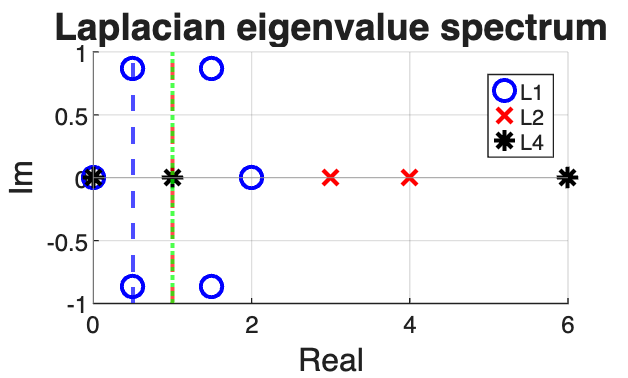

% Calcolo degli autovalori
autovalori_1 = eig(L1);
autovalori_2 = eig(L2);
autovalori_4 = eig(L4);

% Definiamo una tolleranza per escludere lo "zero numerico"
tol = 1e-8; 

% Estraiamo le parti reali
real_1 = real(autovalori_1);
real_2 = real(autovalori_2);
real_4 = real(autovalori_4);

% Troviamo l'autovalore minimo ESCLUDENDO quelli uguali o vicinissimi a 0
min_real_1 = min(real_1(real_1 > tol));
min_real_2 = min(real_2(real_2 > tol));
min_real_4 = min(real_4(real_4 > tol));

% Creazione di una nuova figura
figure; 
hold on;  
grid on;  

% Plot degli autovalori
plot(real_1, imag(autovalori_1), 'bo', 'MarkerSize', 8, 'LineWidth', 1.5);
plot(real_2, imag(autovalori_2), 'rx', 'MarkerSize', 8, 'LineWidth', 1.5);
plot(real_4, imag(autovalori_4), 'k*', 'MarkerSize', 8, 'LineWidth', 1.5);

% --- NUOVE LINEE TRATTEGGIATE (Senza lo zero) ---
% Disegnate in corrispondenza del Fiedler value (connettività algebrica)
xline(min_real_1, 'b--', 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Blu per L1
xline(min_real_2, 'r--', 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Rosso per L2
xline(min_real_4, 'g:', 'LineWidth', 1.5, 'HandleVisibility', 'off'); % Nero per L4

% Disegna gli assi x e y passanti per lo zero 
xline(0, 'Color', [0.6 0.6 0.6], 'LineStyle', '-', 'HandleVisibility', 'off'); 
yline(0, 'Color', [0.6 0.6 0.6], 'LineStyle', '-', 'HandleVisibility', 'off');

% Personalizzazione del grafico
title('Laplacian eigenvalue spectrum', 'FontSize', 14);
xlabel('Real', 'FontSize', 12);
ylabel('Im', 'FontSize', 12);
legend('L1', 'L2', 'L4', 'Location', 'best');

% Chiediamo a MATLAB di ottimizzare la visualizzazione in base ai dati
axis auto; 

hold off;